Cases = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv', 'ReadVariableNames',1);
Cases = table2array(Cases(:,[13:173])); 
Cases = max(Cases,[], 2);


Deaths = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Deaths_CC.csv', 'ReadVariableNames',1);
Deaths = table2array(Deaths(:,[13:173])); 
Deaths = max(Deaths,[],2);

Confounding = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Confounding/Confounding_Dataset.csv', 'ReadVariableNames',1);

% Data = Confounding;
% Data.Cases = Cases;
% Data.Deaths = Deaths; 
% 
% Data(:,[4:14]); 
% Data = table2array(Data(:,[4:14]));

Total_Population = (Confounding.TOT_POP);
Pop_Density = (Confounding.POP_DENSITY);
Black_Pct = (Confounding.BLACK_PCT);
Hisp_Pct = (Confounding.HISPANIC_PCT);
Over_70_Pct = (Confounding.OVER_70_PCT);
Health_Ins_Pct = (Confounding.HLTH_INS_PCT); 
Poverty_Pct = (Confounding.PCT_POVERTY);

**COVID RELATIONSHIPS**

% Cases vs total pop % 
c = corrcoef(Cases, Total_Population); 
c = c(1,2);
fprintf('Correlation coefficent between cases and total population is %f \n', c)

Correlation coefficent between cases and total population is 0.875499 



figure(1)
subplot(2,1,1)
plot(Total_Population,Cases, '*')
ylim([0,60000])
title('Cases vs Total Population')
ylabel('Cases')
xlabel('Total_Population')

% Deaths vs total pop% 
c = corrcoef(Deaths, Total_Population);
c = c(1,2);
fprintf('Correlation coefficent between deaths and total population is %f \n', c)

Correlation coefficent between deaths and total population is 0.657372 


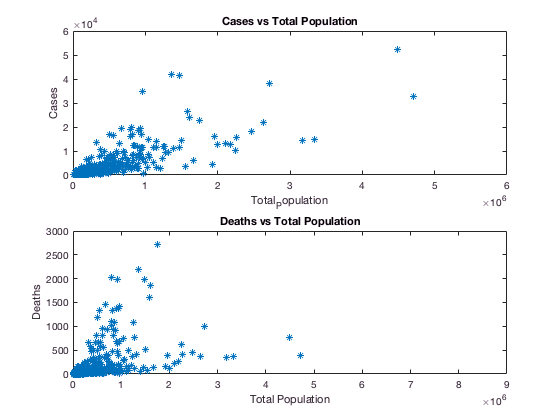


subplot(2,1,2)
plot(Total_Population,Deaths, '*')
title('Deaths vs Total Population')
ylim([0,3000])
ylabel('Deaths')
xlabel('Total Population')

Cases = (Cases./Total_Population)*100000;
Deaths = (Deaths./Total_Population)*100000;
Deaths_Liklihood = Deaths./Cases; 

c = corrcoef(Cases, Total_Population); 
c = c(1,2);
fprintf('After Normalization the correlation coefficent between cases and total population is %f \n', c)

After Normalization the correlation coefficent between cases and total population is 0.207333 



c = corrcoef(Deaths, Total_Population);
c = c(1,2);
fprintf('After Normalization the correlation coefficent between deaths and total population is %f \n', c)

After Normalization the correlation coefficent between deaths and total population is 0.182130 


% Cases vs pop density% 
c = corrcoef(Cases, Pop_Density); 
c = c(1,2);
fprintf('Correlation coefficent between cases and population desnsity is %f \n', c)

Correlation coefficent between cases and population desnsity is 0.323175 



figure(2)
subplot(2,1,1)
plot(Pop_Density,Cases, '*')
title('Cases vs Population Density')
ylabel('Cases')
xlabel('Population Density')

% Deaths vs total pop% 
c = corrcoef(Deaths, Pop_Density);
c = c(1,2);
fprintf('Correlation coefficent between deaths and population density is %f \n', c)

Correlation coefficent between deaths and population density is 0.388009 


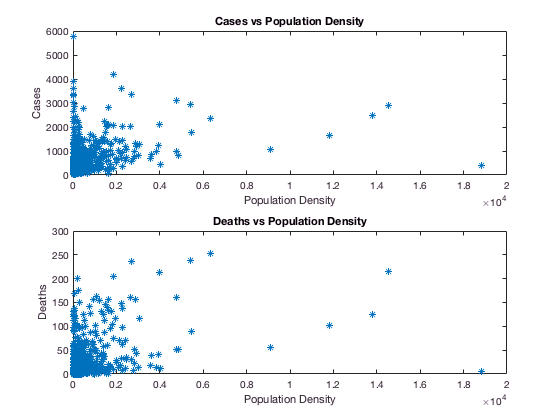


subplot(2,1,2)
plot(Pop_Density,Deaths, '*')
title('Deaths vs Population Density')
ylabel('Deaths')
xlabel('Population Density')

% Cases vs black pct % 
c = corrcoef(Cases, Black_Pct); 
c = c(1,2);
fprintf('Correlation coefficent between cases and black percent of the population is %f \n', c)

Correlation coefficent between cases and black percent of the population is 0.373109 



figure(3)
subplot(2,1,1)
plot(Black_Pct,Cases, '*')
title("Cases vs Black Percent of Population")
ylabel('Cases')
xlabel('Black Percent of Population')

% Deaths vs black pct% 
c = corrcoef(Deaths, Black_Pct);
c = c(1,2);
fprintf('Correlation coefficent between deaths and black percent of the population is %f \n', c)

Correlation coefficent between deaths and black percent of the population is 0.338769 


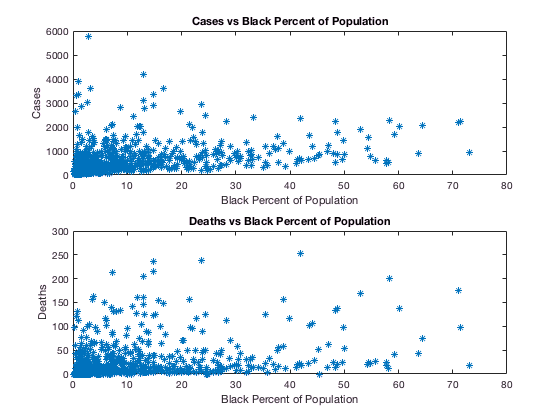


subplot(2,1,2)
plot(Black_Pct,Deaths, '*')
title("Deaths vs Black Percent of Population")
ylabel('Deaths')
xlabel('Black Percent of Population')

% Cases vs Hispanic pct % 
c = corrcoef(Cases, Hisp_Pct); 
c = c(1,2);
fprintf('Correlation coefficent between cases and hispanic percent of the population is %f \n', c)

Correlation coefficent between cases and hispanic percent of the population is 0.301887 



figure(4)
subplot(2,1,1)
plot(Hisp_Pct,Cases, '*')
title("Cases vs Hispanic Percent of Population")
ylabel('Cases')
xlabel('Hispanic Percent of Population')

% Deaths vs Hispanic pct% 
c = corrcoef(Deaths, Hisp_Pct);
c = c(1,2);
fprintf('Correlation coefficent between deaths and hispanic percent of the population is %f \n', c)

Correlation coefficent between deaths and hispanic percent of the population is 0.066655 


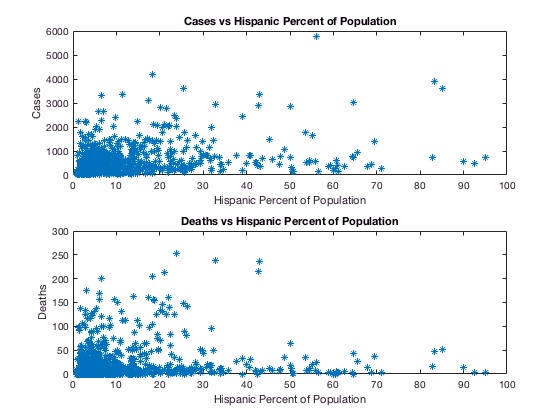


subplot(2,1,2)
plot(Hisp_Pct,Deaths, '*')
title("Deaths vs Hispanic Percent of Population")
ylabel('Deaths')
xlabel('Hispanic Percent of Population')

% Cases vs pct over 70 % 
c = corrcoef(Cases, Over_70_Pct); 
c = c(1,2);
fprintf('Correlation coefficent between cases and percent of the population over 70 is %f \n', c)

Correlation coefficent between cases and percent of the population over 70 is -0.236342 



figure(5)
subplot(2,1,1)
plot(Over_70_Pct,Cases, '*')
title("Cases vs Percent of Population Over 70")
ylabel('Cases')
xlabel('Percent of Population Over 70')

% Deaths vs over 70 pct% 
c = corrcoef(Deaths, Over_70_Pct);
c = c(1,2);
fprintf('Correlation coefficent between deaths and percent of the population over 70 is %f \n', c)

Correlation coefficent between deaths and percent of the population over 70 is -0.122772 


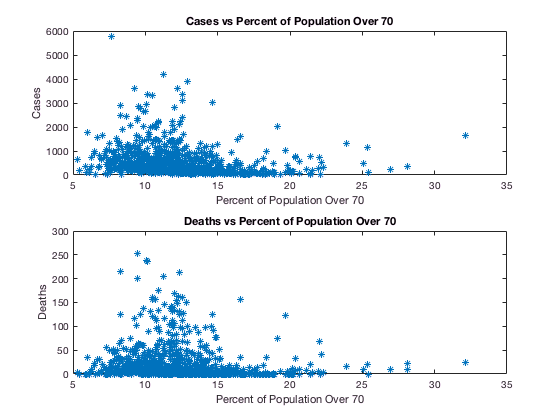


subplot(2,1,2)
plot(Over_70_Pct,Deaths,'*')
title("Deaths vs Percent of Population Over 70")
ylabel('Deaths')
xlabel('Percent of Population Over 70')

% Cases vs Health Insurance pct % 
c = corrcoef(Cases, Health_Ins_Pct); 
c = c(1,2);
fprintf('Correlation coefficent between cases and percent of the population with health insurance is %f \n', c)

Correlation coefficent between cases and percent of the population with health insurance is -0.156541 



figure(6)
subplot(2,1,1)
plot(Health_Ins_Pct,Cases, '*')
title("Cases vs Percent of Population With Health Insurance")
ylabel('Cases')
xlabel('Percent of Population With Health Insurance')

% Deaths vs Health Insurance pct% 
c = corrcoef(Deaths, Health_Ins_Pct);
c = c(1,2);
fprintf('Correlation coefficent between deaths and percent of the population with health insurance is %f \n', c)

Correlation coefficent between deaths and percent of the population with health insurance is 0.062094 


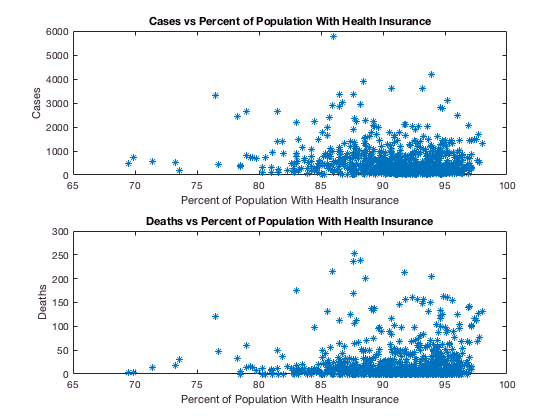


subplot(2,1,2)
plot(Health_Ins_Pct,Deaths, '*')
title("Deaths vs Percent of Population With Health Insurance")
ylabel('Deaths')
xlabel('Percent of Population With Health Insurance')

% Cases vs Poverty pct % 
c = corrcoef(Cases, Poverty_Pct);
c = c(1,2);
fprintf('Correlation coefficent between cases and percent of the population in poverty is %f \n', c)

Correlation coefficent between cases and percent of the population in poverty is 0.116292 



figure(6)
subplot(2,1,1)
plot(Poverty_Pct,Cases,'*')
title("Cases vs Percent of Population in Poverty")
ylabel('Cases')
xlabel('Percent of Population in Poverty')

% Deaths vs Poverty pct% 
c = corrcoef(Deaths, Poverty_Pct);
c = c(1,2);
fprintf('Correlation coefficent between deaths and percent of the population in poverty is %f \n', c)

Correlation coefficent between deaths and percent of the population in poverty is 0.003964 


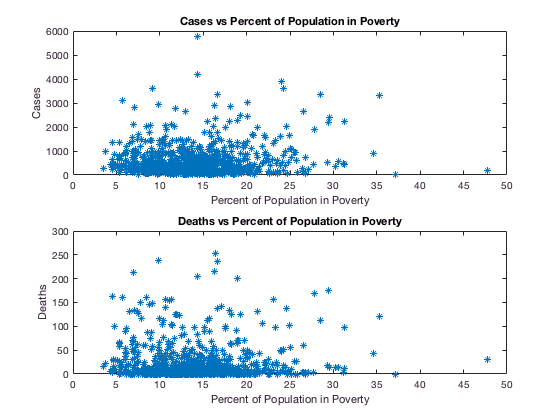


subplot(2,1,2)
plot(Poverty_Pct,Deaths, '*')
title("Deaths vs Percent of Population in Poverty")
ylabel('Deaths')
xlabel('Percent of Population in Poverty')

T = table(Cases, Deaths,Deaths_Liklihood)

T = 832×3 table
    Cases     Deaths     Deaths_Liklihood
    ______    _______    ________________

     307.3     4.0316       0.01312      
    666.17     9.0512      0.013587      
     841.8     6.9917     0.0083056      
    611.14     12.712        0.0208      
    409.89     4.7222      0.011521      
    666.14     21.258      0.031912      
    283.45      1.609     0.0056764      
     894.7     32.429      0.036246      
      1695     41.504      0.024486      
    819.69     2.5067     0.0030581      
    835.04          0             0      
    497.01     10.565      0.021257      
      2221     96.564      0.043478      
    978.72     17.196       0.01757      
    3312.1     119.63      0.036119      
    521.75     6.3531      0.012177      
    1352.8     64.122      0.047398      
    572.03     9.2562      0.016181      
    1634.5     23.688      0.014493      

%writetable(T, '/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Normalized_Cases_Deaths.csv'); 

**AQI RELATIONSHIPS **

AQI_data = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/AQI_Features.csv');
med_AQI = AQI_data.MedianAQI;

% AQI vs Poverty
c = corrcoef(med_AQI, Poverty_Pct);
c = c(1,2);
fprintf('Correlation coefficent between median AQI and percent of the population in poverty is %f \n', c)

Correlation coefficent between median AQI and percent of the population in poverty is 0.034720 


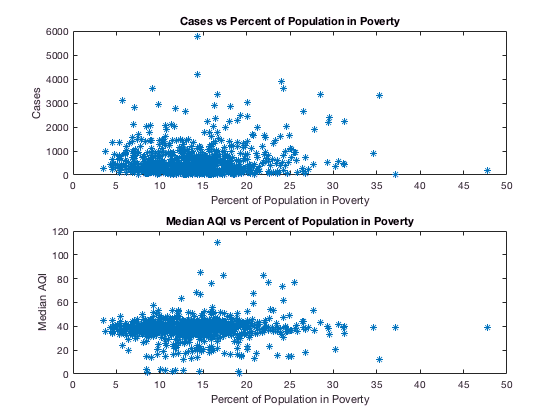


plot(Poverty_Pct,med_AQI, '*')
title("Median AQI vs Percent of Population in Poverty")
ylabel('Median AQI')
xlabel('Percent of Population in Poverty')


% AQI vs Health Insurance
c = corrcoef(med_AQI, Health_Ins_Pct);
c = c(1,2);
fprintf('Correlation coefficent between median AQI and percent of the population with health insurance is %f \n', c)

Correlation coefficent between median AQI and percent of the population with health insurance is -0.015969 


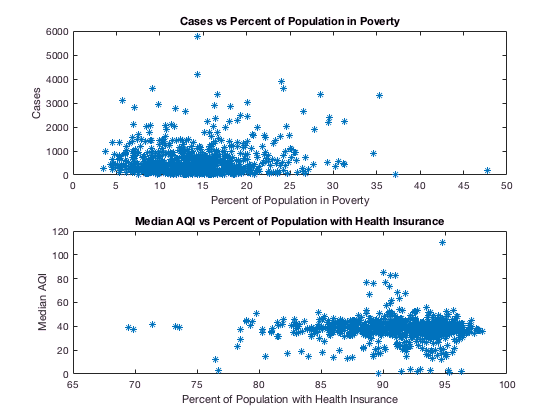


plot(Health_Ins_Pct,med_AQI, '*')
title("Median AQI vs Percent of Population with Health Insurance")
ylabel('Median AQI')
xlabel('Percent of Population with Health Insurance')